Sphere parameters

x0 =0.05

x0 = 0.0500

y0 = -0.05

y0 = -0.0500

z0 = 0.5

z0 = 0.5000

r =0.25

r = 0.2500

numInliers =10000%350 pöttyös

numInliers = 10000

W = [x0^2 x0*y0 x0*z0 y0^2 y0*z0 z0^2]

W =     0.0025   -0.0025    0.0250    0.0025   -0.0250    0.2500


Camera parameters

f = 800;%2000;%1050;
u0 = 960;
v0 = 600;
fu = f;
fv = f;
intrinsic = cameraIntrinsics([fu fv], [u0 v0], [2*u0, 2*v0]);

Inlier parameters

rndNum = 66%350 pöttyös

rndNum = 66

precision_pix = 1;
magic_number = 2000%40;%101;%50;%40;% 67; 101

magic_number = 2000

Generate rndNum inlier point

nofile = 1;
rndN_pix = [];
rndN_m = [];
if nofile == 1   
    s = SphereConverter([x0, y0, z0, r]);
    pE = sphereO2parametricEllipseO(s);
    inliers_m = generateEllipsePoints(pE, numInliers);
    %outliers_m = [-0.065 -0.011] + [0:0.001:0.01; zeros(11, 1)']';
    %inliers_m = [inliers_m; outliers_m]; 
    inliers_pix = round(ImageData.meter2pixel(inliers_m, intrinsic));
    inliers_pix = unique(inliers_pix,'rows');
    if precision_pix ~= 0
        sigma = precision_pix;
        inliers_pix = round(inliers_pix + sqrt(sigma)*randn(size(inliers_pix)));%![awgn(inliers_pix(:, 1),10,'measured') awgn(inliers_pix(:, 2),10,'measured')];
        %inliers_pix = round(ImageData.meter2pixel(inliers_m, intrinsic) / precision_pix) * precision_pix;
    end
    if rndNum > length(inliers_pix)
        rndNum = inliers_pix_min;
    end
    idxs = 1: length(inliers_pix); %rndNum;%randsample(length(inliers_m), rndNum);
    rndN_pix = inliers_pix(idxs(:),:);
    rndN_m = ImageData.pixel2meter(rndN_pix, intrinsic);
    
    %rndN_m = inliers_m ;
    %rndN_m= inliers_m(idxs(:),:);
else
    load('ellipse_full_contour00_045_015_075_025_800_960_600.mat','rndN_m', 'rndN_pix');   
end

Estimate implicit ellipse parameter ground truth

%{
EP_GT = sphereO2implicitEllipseO(s);
pts = PointSet2D(rndN_pix);
pE_Dir = fitEllipse(pts);
ellipseDir = EllipseConverter(pE_Dir);
s_Dir = parametricEllipseO2SphereO(pE_Dir, r);
%}

Estimators

idxs = 1:magic_number;
pts = PointSet2D(rndN_m);

sphereSun = fitSphereSun16(pts, r, idxs)

sphereSun =   SphereConverter with properties:

    parameters: [0.0500 -0.0500 0.5000 0.2500]
            s0: [0.0500 -0.0500 0.5000]
             r: 0.2500


sphereDir = fitSphere(pts, r, idxs)

sphereDir =   SphereConverter with properties:

    parameters: [0.0500 -0.0500 0.5000 0.2500]
            s0: [0.0500 -0.0500 0.5000]
             r: 0.2500


EP_Sun = sphereO2implicitEllipseO(sphereSun);

pE_Shi19 = fitEllipseShi19B(pts, r, idxs);

A3


pE_Dir = fitEllipse(pts, idxs);


Conversions - pixel function

ellipseSun = EllipseConverter(EP_Sun);
pe_Sun = ellipseSun.parametricEllipse;

pE_Dir = convertToPixel(pE_Dir, u0, v0, fu, fv);
pe_Sun = convertToPixel(pe_Sun, u0, v0, fu, fv);
pE_Shi19 = convertToPixel(pE_Shi19, u0, v0, fu, fv);

ellipseShi19 = EllipseConverter(pE_Shi19);
ellipseDir = EllipseConverter(pE_Dir);
ellipseSun = EllipseConverter(pe_Sun);

EP_Shi19 = ellipseShi19.implicitEllipse;
EP_Dir = ellipseDir.implicitEllipse;
EP_Sun = ellipseSun.implicitEllipse;

Construct symbolic ellipse equation

syms u v;
vars = [u^2; u*v; v^2; u; v; 1];
funcShi19(u, v) = EP_Shi19.coefficients * vars;
funcSun(u, v) = EP_Sun.coefficients * vars;
funcDir(u, v) = EP_Dir.coefficients * vars;

Plot image with pixels

colors = [  0, 0.4470, 0.7410;	   
          	0.8500, 0.3250, 0.0980;	         
          	0.9290, 0.6940, 0.1250;	       
          	0.4940, 0.1840, 0.5560;	      
          	0.4660, 0.6740, 0.1880;	    
          	0.3010, 0.7450, 0.9330;	  
          	0.6350, 0.0780, 0.1840;
            0.01,    0.4,    0.25;
            0.8,    0.1,    0.1];


img = ones(2*v0, 2*u0, 3);
%{
for i = 1 : length(inliers_pix)
    img( inliers_pix(i, 2), inliers_pix(i, 1) , 1:3) = [0 0 1];
end
for i = 1 : length(rndN_pix)
    img( rndN_pix(i, 2), rndN_pix(i, 1) , 1:3) = [1 0 0];
end
%}
for i = 1 : length(rndN_pix)
    img( rndN_pix(i, 2), rndN_pix(i, 1) , 1:3) = [0 0 0];
end
for i = 1 : magic_number
    img( rndN_pix(i, 2), rndN_pix(i, 1) , 1:3) = colors(8, :);
end


fs = 12;        

h = figure

h =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 198 560 420]
       Units: 'pixels'

  Show all properties


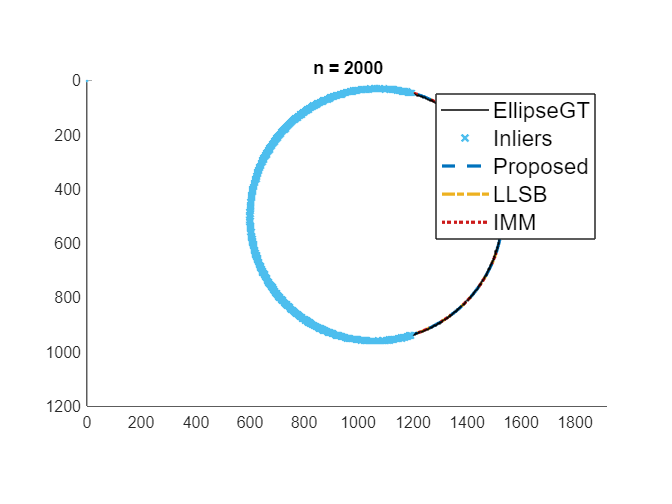

hold on;
axis equal;
set(gca, 'YDir','reverse')
%xlim([1100 1900]);
%ylim([450 1100]);
xlim([0 2*u0]);
ylim([0 2*v0]);
image(img);
plot(0, 0, 'k');
scatter(0, 0, 1, colors(6, :), 'x','LineWidth',1.5);
fimplicit(funcDir == 0, [0 2*u0],'--','Color', colors(1, :), 'LineWidth',2);
fimplicit(funcSun == 0, [0 2*u0],'-.', 'Color', colors(3, :), 'LineWidth',2);
fimplicit(funcShi19 == 0, [0 2*u0],':', 'Color', colors(9, :),'LineWidth',2);
fimplicit(funcDir == 0, [0 2*u0],'--','Color', colors(1, :), 'LineWidth',2);
scatter(rndN_pix(1:length(rndN_pix), 1), rndN_pix(1:length(rndN_pix), 2), 1, 'k','s', 'filled', 'LineWidth',1);
scatter(rndN_pix(1:magic_number, 1), rndN_pix(1:magic_number, 2), 1, colors(6, :), 'x', 'LineWidth',5);
legend({'EllipseGT', 'Inliers', 'Proposed', 'LLSB', 'IMM'}, 'FontSize',14);
%title(strcat(num2str(magic_number), ' inliers'));
title(strcat('n = ', {' '},num2str(magic_number)));

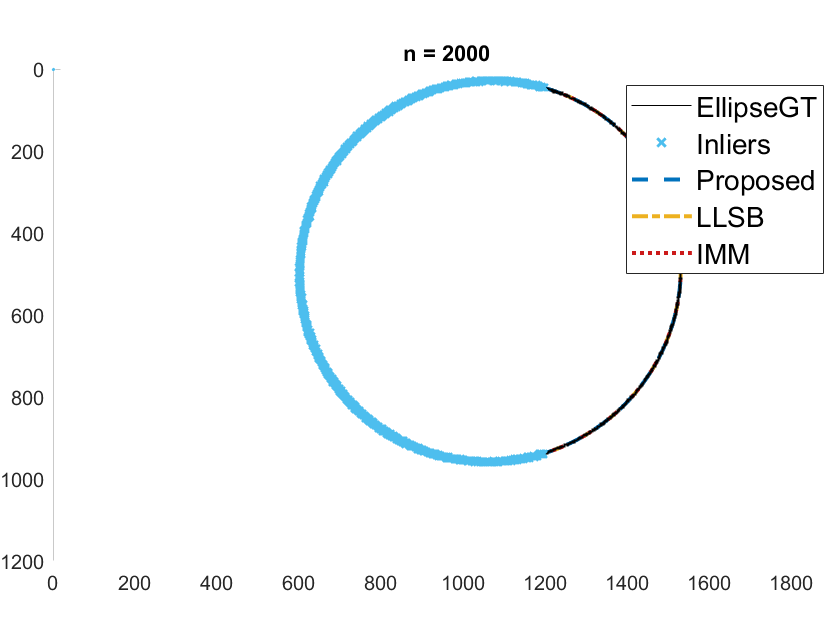

outputFile= strcat('Matlab2_illcond_l_', num2str(magic_number), '.pdf');
set(gca,'LooseInset',get(gca,'TightInset'));
set(h,'Units','Inches');
pos = get(h,'Position');
set(h,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])
print(outputFile,'-dpdf','-r0')